## Parcial 1 Repaso - Santiago Hoyos

- El uso de splines cúbicos es muy común para describir contornos de imágenes. Suponga que usted trabaja para una empresa que tiene un proyecto donde se necesita detectar la presencia de personas en una imagen. Para ello, la empresa le solicita crear un primer prototipo del software a partir de la siguiente figura:

a. Grafique la nube de puntos.

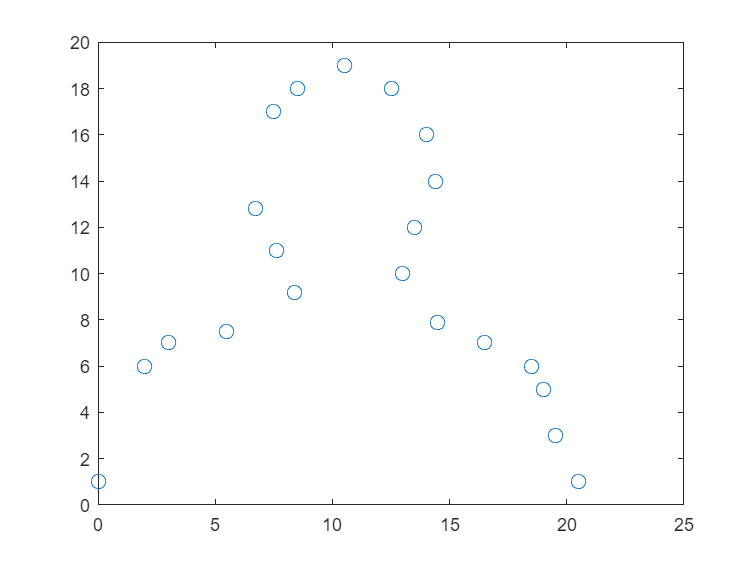

clear
syms x

x_1 = [0, 2, 3, 5.5, 8.4, 7.6, 6.7, 7.5, 8.5, 10.5, 12.5, 14, 14.4, 13.5, 13, 14.5, 16.5, 18.5, 19, 19.5, 20.5];
y_1 = [1, 6, 7, 7.5, 9.2, 11, 12.8, 17, 18, 19, 18, 16, 14, 12, 10, 7.9, 7, 6, 5, 3, 1];

% Graficar la tabla de datos
figure;
plot(x_1, y_1, 'o', 'MarkerSize', 8);
hold on;

b. Genere un código que, a partir de los puntos señalados en la imagen, permita obtener el contorno de la persona.

x_i = [0, 2, 3, 5.5, 8.4];
y_i = [1, 6, 7, 7.5, 9.2];

x_i2 = [6.7, 7.6, 8.4];
y_i2 = [12.8, 11, 9.2];

x_i3 = [6.7, 7.5, 8.5, 10.5, 12.5, 14, 14.4];
y_i3 = [12.8, 17, 18, 19, 18, 16, 14];

x_i4 = [13, 13.5, 14.4];
y_i4 = [10, 12, 14];

x_i5 = [13, 14.5, 16.5, 18.5, 19, 19.5, 20.5];
y_i5 = [10, 7.9, 7, 6, 5, 3, 1];

s1 = generate_splines(x_i, y_i);
s2 = generate_splines(x_i2, y_i2);
s3 = generate_splines(x_i3, y_i3);
s4 = generate_splines(x_i4, y_i4);
s5 = generate_splines(x_i5, y_i5);

c. Especifique las curvas encontradas de los splines cúbicos.

% Imprimir los resultados en decimales
for i = 1:length(s1)
    disp(['Spline S', num2str(i-1), '(x):']);
    disp(s1(i));  % 4 es la cantidad de decimales deseada
end

Spline S0(x):


$$-\frac{547633\,x^{3}}{4701480}+\frac{1743029\,x}{587685}+1$$

Spline S1(x):


$$\frac{1843159\,x}{1175370}-\frac{547633\,{\left(x-2\right)}^{2}}{783580}+\frac{43903\,{\left(x-2\right)}^{3}}{335820}+\frac{1682951}{587685}$$

Spline S2(x):


$$\frac{1322483\,x}{2350740}-\frac{60078\,{\left(x-3\right)}^{2}}{195895}+\frac{27143\,{\left(x-3\right)}^{3}}{419775}+\frac{4162577}{783580}$$

Spline S3(x):


$$\frac{283909\,x}{1175370}+\frac{13969\,{\left(x-\frac{11}{2}\right)}^{2}}{78358}-\frac{69845\,{\left(x-\frac{11}{2}\right)}^{3}}{3408573}+\frac{14507551}{2350740}$$


% Imprimir los resultados en decimales
for i = 1:length(s2)
    disp(['Spline S', num2str(i-1), '(x):']);
    disp(s2(i));  % 4 es la cantidad de decimales deseada
end

Spline S0(x):


$$\frac{35029}{1360}-\frac{25\,{\left(x-\frac{67}{10}\right)}^{3}}{306}-\frac{263\,x}{136}$$

Spline S1(x):


$$\frac{25\,{\left(x-\frac{38}{5}\right)}^{3}}{272}-\frac{15\,{\left(x-\frac{38}{5}\right)}^{2}}{68}-\frac{145\,x}{68}+\frac{925}{34}$$


for i = 1:length(s3)
    disp(['Spline S', num2str(i-1), '(x):']);
    disp(s3(i));  % 4 es la cantidad de decimales deseada
end

Spline S0(x):


$$\frac{1566761\,x}{251184}-\frac{6201125\,{\left(x-\frac{67}{10}\right)}^{3}}{4018944}-\frac{14564287}{502368}$$

Spline S1(x):


$$\frac{411313\,x}{125592}-\frac{1240225\,{\left(x-\frac{15}{2}\right)}^{2}}{334912}+\frac{1434907\,{\left(x-\frac{15}{2}\right)}^{3}}{1004736}-\frac{633189}{83728}$$

Spline S2(x):


$$\frac{153875\,x}{1004736}+\frac{97341\,{\left(x-\frac{17}{2}\right)}^{2}}{167456}-\frac{819599\,{\left(x-\frac{17}{2}\right)}^{3}}{4018944}+\frac{33554621}{2009472}$$

Spline S3(x):


$$\frac{15631\,x}{502368}-\frac{430235\,{\left(x-\frac{21}{2}\right)}^{2}}{669824}+\frac{757075\,{\left(x-\frac{21}{2}\right)}^{3}}{4018944}+\frac{6253911}{334912}$$

Spline S4(x):


$$\frac{40855\,{\left(x-\frac{25}{2}\right)}^{2}}{83728}-\frac{278923\,x}{1004736}-\frac{598705\,{\left(x-\frac{25}{2}\right)}^{3}}{753552}+\frac{43143571}{2009472}$$

Spline S5(x):


$$\frac{2584975\,{\left(x-14\right)}^{3}}{1004736}-\frac{516995\,{\left(x-14\right)}^{2}}{167456}-\frac{524561\,x}{125592}+\frac{4676663}{62796}$$


for i = 1:length(s4)
    disp(['Spline S', num2str(i-1), '(x):']);
    disp(s4(i));  % 4 es la cantidad de decimales deseada
end

Spline S0(x):


$$\frac{272\,x}{63}-\frac{80\,{\left(x-13\right)}^{3}}{63}-\frac{2906}{63}$$

Spline S1(x):


$$\frac{212\,x}{63}-\frac{40\,{\left(x-\frac{27}{2}\right)}^{2}}{21}+\frac{400\,{\left(x-\frac{27}{2}\right)}^{3}}{567}-\frac{234}{7}$$


for i = 1:length(s5)
    disp(['Spline S', num2str(i-1), '(x):']);
    disp(s5(i));  % 4 es la cantidad de decimales deseada
end

Spline S0(x):


$$\frac{33\,{\left(x-13\right)}^{3}}{370}-\frac{2369\,x}{1480}+\frac{45597}{1480}$$

Spline S1(x):


$$\frac{297\,{\left(x-\frac{29}{2}\right)}^{2}}{740}-\frac{739\,x}{740}-\frac{47\,{\left(x-\frac{29}{2}\right)}^{3}}{740}+\frac{33123}{1480}$$

Spline S2(x):


$$\frac{3\,{\left(x-\frac{33}{2}\right)}^{2}}{148}-\frac{23\,x}{148}-\frac{57\,{\left(x-\frac{33}{2}\right)}^{3}}{592}+\frac{2831}{296}$$

Spline S3(x):


$$\frac{115}{4}-\frac{165\,{\left(x-\frac{37}{2}\right)}^{2}}{296}-\frac{291\,{\left(x-\frac{37}{2}\right)}^{3}}{148}-\frac{91\,x}{74}$$

Spline S4(x):


$$\frac{601\,{\left(x-19\right)}^{3}}{148}-\frac{519\,{\left(x-19\right)}^{2}}{148}-\frac{1931\,x}{592}+\frac{39649}{592}$$

Spline S5(x):


$$\frac{765\,{\left(x-\frac{39}{2}\right)}^{2}}{296}-\frac{551\,x}{148}-\frac{255\,{\left(x-\frac{39}{2}\right)}^{3}}{296}+\frac{22377}{296}$$

d. Grafique el contorno generado a partir de los splines cúbicos

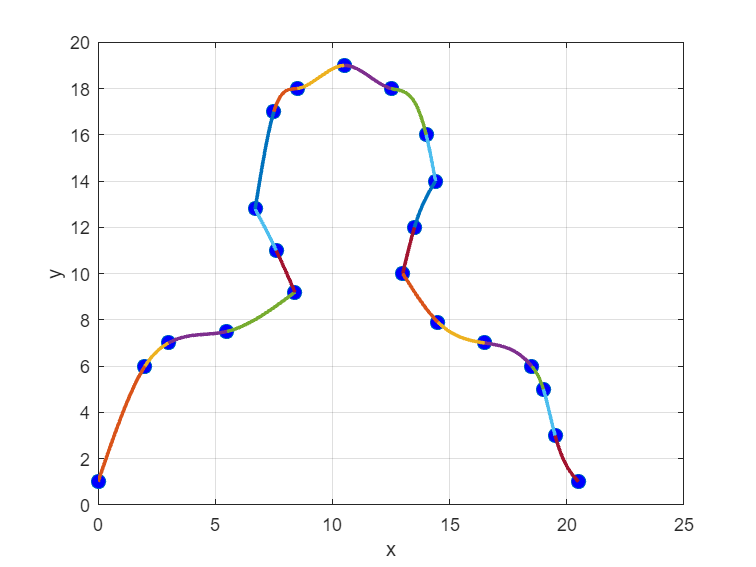

%PLOT
figure;
plot(x_1(1:length(x_1)), y_1(1:length(x_1)), 'o', 'MarkerSize', 8, 'MarkerFaceColor', 'b');
hold on;

for i = 1:length(s1)
    eval = linspace(x_i(i), x_i(i+1), 50);
    f_eval = subs(s1(i), x, eval);
    plot(eval, f_eval, 'LineWidth', 2);
end

for i = 1:length(s2)
    eval = linspace(x_i2(i), x_i2(i+1), 50);
    f_eval = subs(s2(i), x, eval);
    plot(eval, f_eval, 'LineWidth', 2);
end

for i = 1:length(s3)
    eval = linspace(x_i3(i), x_i3(i+1), 50);
    f_eval = subs(s3(i), x, eval);
    plot(eval, f_eval, 'LineWidth', 2);
end

for i = 1:length(s4)
    eval = linspace(x_i4(i), x_i4(i+1), 50);
    f_eval = subs(s4(i), x, eval);
    plot(eval, f_eval, 'LineWidth', 2);
end

for i = 1:length(s5)
    eval = linspace(x_i5(i), x_i5(i+1), 50);
    f_eval = subs(s5(i), x, eval);
    plot(eval, f_eval, 'LineWidth', 2);
end


hold off;

xlabel('x');
ylabel('y');
grid on;

### Punto 2

Utilice la interpolación inversa para calcular 𝑔 cuando 𝑦 = 55000𝑚. Evidencie el proceso para el cálculo de este punto

% Datos de la tabla
x_data = [0, 30000, 60000, 90000, 120000];
f_data = [9.8100, 9.7487, 9.6879, 9.6278, 9.5682];
n = length(x_data);

% Símbolo 'x' para representar el polinomio
syms x;

% Calculando el polinomio interpolador de Lagrange
P = 0;

for i = 1:n
    L = 1;
    for j = 1:n
        if j ~= i
            L = L * (x - x_data(j)) / (x_data(i) - x_data(j));
        end
    end
    P = P + f_data(i) * L;
end

% Simplificando el polinomio
simplified_P = simplify(P);

% Imprimiendo el polinomio interpolador simplificado
disp("Polinomio interpolador de Lagrange simplificado:");

Polinomio interpolador de Lagrange simplificado:


disp(simplified_P);

$$-\frac{x^{4}}{48600000000000000000000}+\frac{x^{3}}{202500000000000000}-\frac{x^{2}}{27000000000000}-\frac{3683\,x}{1800000000}+\frac{981}{100}$$

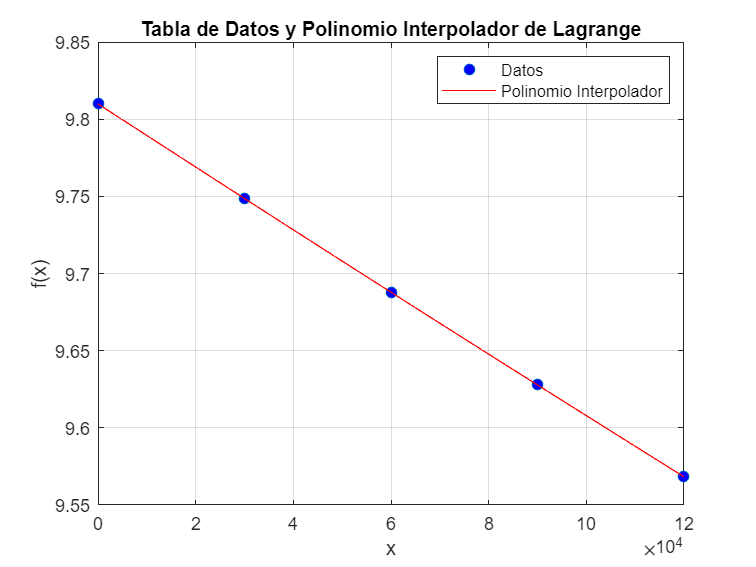


% Graficando la tabla de datos y el polinomio interpolador
x_eval = linspace(min(x_data), max(x_data), 100);
P_eval = subs(simplified_P, x, x_eval);

figure;
plot(x_data, f_data, 'o', 'MarkerFaceColor', 'b', 'DisplayName', 'Datos');
hold on;
plot(x_eval, P_eval, 'r', 'DisplayName', 'Polinomio Interpolador');
xlabel('x');
ylabel('f(x)');
title('Tabla de Datos y Polinomio Interpolador de Lagrange');
legend;
grid on;


% Calculando f(55000)
x_value = 55000;
f_2_8 = subs(simplified_P, x, x_value);
simplified_f = simplify(f_2_8);
disp("El valor de f(2.8) es:");

El valor de f(2.8) es:


disp(double(simplified_f));

    9.6980



Función

function s = generate_splines(x_i, y_i)
    syms x;
    
    n = length(x_i);
    s = sym('s', [1 n-1]);
    df = sym('d', [1 n-1]);
    dd = sym('dd', [1 n-1]); 
    eqn = sym('eqn', [1 4*(n-1)]);
    iter = 1;
    variables = sym('a', [4*(n-1), 1]);
    
    for i = 1:n-1
        a = sym("a" + i);
        b = sym("b" + i);
        c = sym("c" + i);
        d = sym("d" + i);
        variables(i) = a;
        variables(i + (n-1)) = b;
        variables(i + 2*(n-1)) = c;
        variables(i + 3*(n-1)) = d;
        s(i) = a + b*(x - x_i(i)) + c*(x - x_i(i))^2 + d*(x - x_i(i))^3;
        df(i) = b + 2*c*(x - x_i(i)) + 3*d*(x - x_i(i))^2;
        dd(i) = 2*c + 6*d*(x - x_i(i));
        
        if i == n-1
            eqn(iter) = subs(s(i), x, x_i(i)) == y_i(i);
            iter = iter + 1;
            eqn(iter) = subs(s(i), x, x_i(i+1)) == y_i(i+1);
        else
            eqn(iter) = subs(s(i), x, x_i(i)) == y_i(i);
        end
        iter = iter + 1;
    end

    for i = 1:n-2
        eqn(iter) = subs(s(i), x, x_i(i+1)) == subs(s(i+1), x, x_i(i+1));
        iter = iter + 1;
        eqn(iter) = subs(df(i), x, x_i(i+1)) == subs(df(i+1), x, x_i(i+1));
        iter = iter + 1;
        eqn(iter) = subs(dd(i), x, x_i(i+1)) == subs(dd(i+1), x, x_i(i+1));
        iter = iter + 1;
    end

    eqn(iter) = subs(dd(1), x, x_i(1)) == 0;
    iter = iter + 1;
    eqn(iter) = subs(dd(n-1), x, x_i(n)) == 0;

    [A, b] = equationsToMatrix(eqn);
    X = linsolve(A, b);

    for i = 1:n-1
        s(i) = subs(s(i), variables, X);
        eval = linspace(x_i(i), x_i(i+1), 50);
        f_eval = subs(s(i), x, eval);
    end
end